# Set data

N = 1025;
lambda = 532;
D = 50E6; % lens aperture in nm
f = 100E6; % focal length in mm
p = [2*f, 4*f]; % object distance
p = reshape(repmat(p,(N-1)*(N-1),1),N-1,N-1,[]);
Endpoint = lambda;


## Setup sampling points

x = linspace(-Endpoint,Endpoint,N);
x = x(1:end-1);
dx = x(2)-x(1);
xi = linspace(-1/Endpoint,1/Endpoint,N);
xi = xi(1:end-1);
y = linspace(-Endpoint,Endpoint,N);
y = y(1:end-1);
dy = y(2)-y(1);
eta = linspace(-1/Endpoint,1/Endpoint,N);
eta = eta(1:end-1);

[X,Y] = meshgrid(x,y);
[Xi,Eta] = meshgrid(xi,eta);


## Read Object

obj_raw = imread('my_cat.jpg');
obj_gray = rgb2gray(obj_raw);
obj = obj_gray./max(max(obj_gray));
obj = imresize(obj,[N-1 N-1]);


## Setup CTF for lens

CTF = Xi.^2 + Eta.^2 <= (D/(lambda.*p)).^2;

## Fourier Transform of Object

uobj = fftshift(obj);
UOBJ = dx*dy*fft2(uobj);
UOBJ = ifftshift(UOBJ);

## Convolution in Fourier Domain

UIMGSALE = UOBJ .* CTF;

## Inverse Fourier Transform

UIMGSALE = fftshift(UIMGSALE);
UIMGSALE = 1/(dx*dy)*ifft2(UIMGSALE);
UIMGSALE = ifftshift(UIMGSALE);

## Gaussian Imaging Equation

q = 1/((1/f)-(1/p));
m = -q./p;
UIMG = UIMGSALE;

## Show Figures

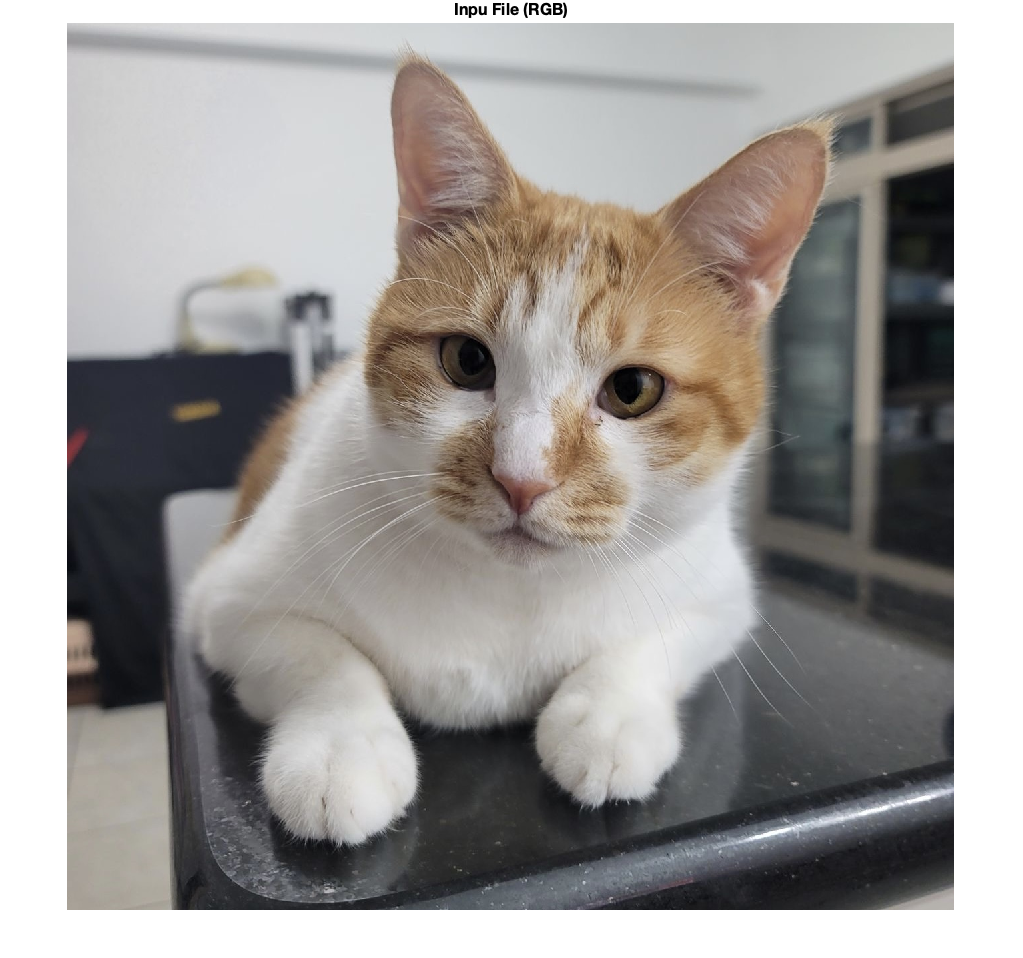

figure();
imshow(obj_raw);
title('Inpu File (RGB)', "FontSize",16)

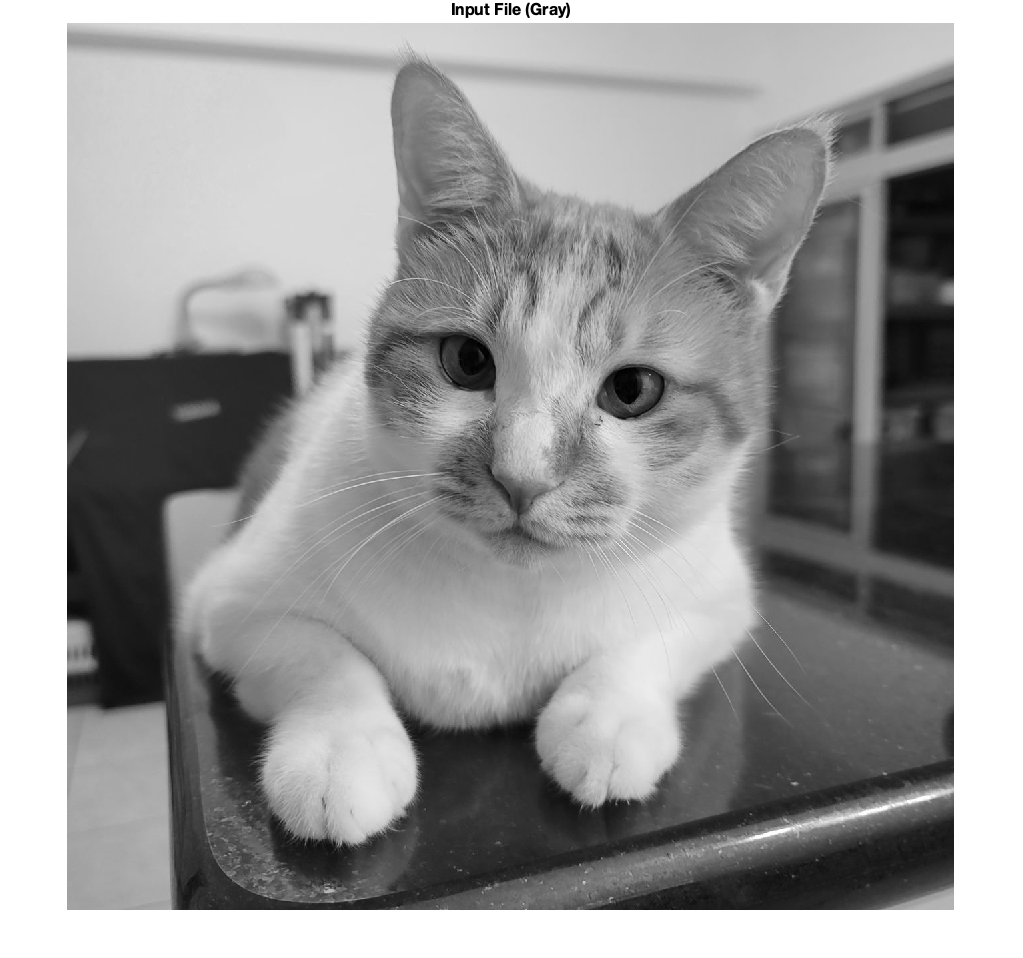


figure();
imshow(obj_gray);
title('Input File (Gray)', "FontSize",16)

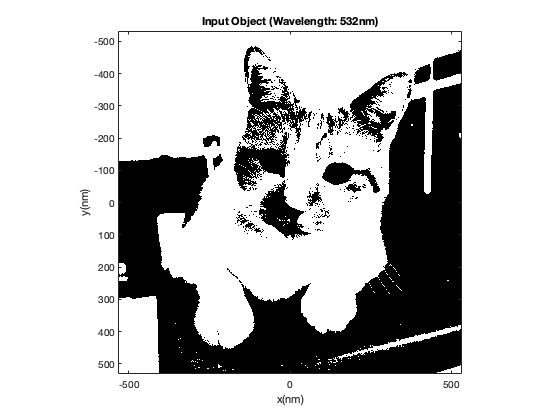



figure();
imagesc(x,y,real(obj))
axis square
axis ij
colormap gray
title(['Input Object (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')

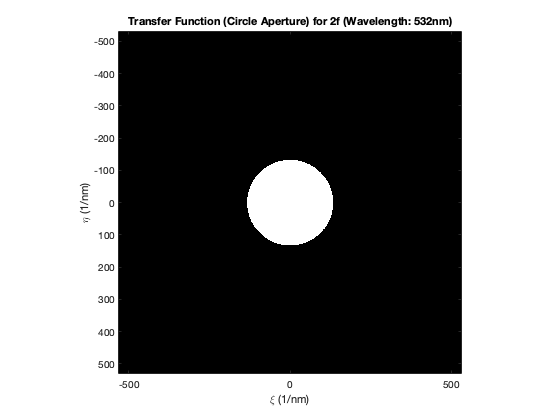


figure()
imagesc(x,y,real(CTF(:,:,1)))
axis square
axis ij
colormap gray
title(['Transfer Function (Circle Aperture) for 2f (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('\xi (1/nm)')
ylabel('\eta (1/nm)')

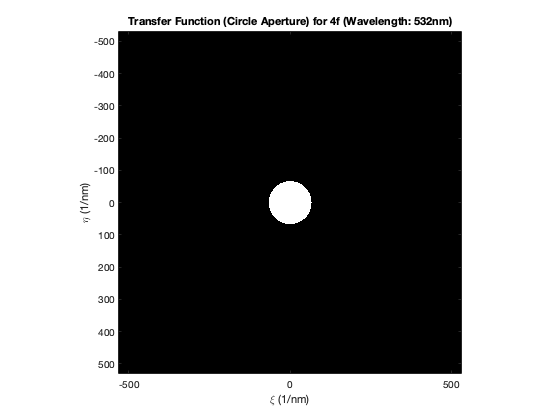


figure()
imagesc(x,y,real(CTF(:,:,2)))
axis square
axis ij
colormap gray
title(['Transfer Function (Circle Aperture) for 4f (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('\xi (1/nm)')
ylabel('\eta (1/nm)')

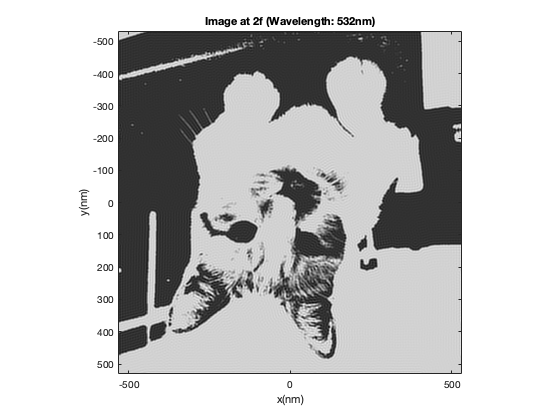


figure()
imagesc( x*(m(1,1,1)), y*(m(1,1,1)), real(UIMG(:,:,1)))
axis square
axis ij
colormap gray
title(['Image at 2f (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')
xlim([min(x) max(x)])
ylim([min(y) max(y)])

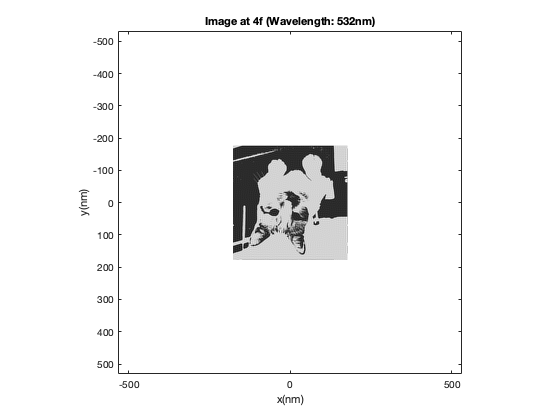


figure()
imagesc( x*(m(1,1,2)), y*(m(1,1,2)), real(UIMG(:,:,2)))
axis square
axis ij
colormap gray
title(['Image at 4f (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')
xlim([min(x) max(x)])
ylim([min(y) max(y)])